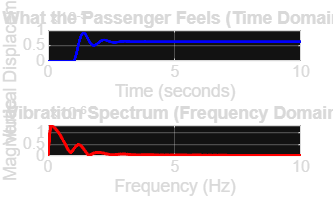

    %% 1. Extract the Data
% Simulink bundles results into 'out'. We need to pull them out.
if exist('out', 'var')
    displacement = out.sim_data;  % The vibration amplitude (from your specific block)
    t = out.tout;                 % The time vector (automatically generated by Simulink)
else
    error('Please click the Green RUN button in Simulink first!');
end

%% 2. Plot Time Domain (The "Bump" Response)
figure('Color', 'w'); 
subplot(2,1,1);
plot(t, displacement, 'b', 'LineWidth', 1.5);
grid on;
title('What the Passenger Feels (Time Domain)');
xlabel('Time (seconds)'); ylabel('Vertical Displacement (m)');

%% 3. FFT Analysis (Frequency Response)
% This tells us the resonant frequency
Fs = 1000;              % Your sampling frequency
L = length(displacement);

% Remove gravity/offset so we only analyze vibration
y_detrend = displacement - mean(displacement); 

% Compute FFT
Y = fft(y_detrend);
P2 = abs(Y/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(floor(L/2)))/L;

% Plot Frequency Domain
subplot(2,1,2);
plot(f, P1, 'r', 'LineWidth', 1.5);
grid on;
title('Vibration Spectrum (Frequency Domain)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 10]); % Focus on 0-10 Hz range


% Diagnostic
[peak_val, peak_idx] = max(P1);
fprintf('Result: The suspension is oscillating at %.2f Hz\n', f(peak_idx));

Result: The suspension is oscillating at 0.10 Hz
